% Add the path to the ENIGMA TOOLBOX matlab folder
addpath(genpath('/path/to/ENIGMA/matlab/'));

## Figure 1b. Load example data

% Load example data
[cov, metr1_SubVol, metr2_CortThick, metr3_CortSurf] = load_example_data();

% Z-score data in patients relative to controls
groups       = cov.Dx;
controlGroup = 0;
CortThick_Z  = zscore_matrix(metr2_CortThick(:, 2:end-5), groups, controlGroup);
SubVol_Z     = zscore_matrix(metr1_SubVol(:, 2:end-1), groups, controlGroup);

% Extract data for a specific group (e.g., individuals with left TLE)
CortThick_Z_LTLE = CortThick_Z(cov.SDx == 3, :);
SubVol_Z_LTLE    = SubVol_Z(cov.SDx == 3, :);

## Figure 1d. Load summary statistics

% Load summary statistics for a given disease (e.g., epilepsy)
sum_stats = load_summary_stats('epilepsy');

% List available summary statistic tables
sum_stats

## Figure 2b. Surface data visualization

% Re-order subcortical data (alphabetically and by hemisphere)
SubVol_Z_LTLE_r = reorder_sctx(SubVol_Z_LTLE);

% Mean data across all individuals with left TLE
CortThick_Z_LTLE_mean = varfun(@mean, CortThick_Z_LTLE);
SubVol_Z_LTLE_r_mean  = varfun(@mean, SubVol_Z_LTLE_r);

% Map parcellated data to the surface (cortical values only)
CortThick_Z_LTLE_mean_fsa5 = parcel_to_surface(CortThick_Z_LTLE_mean{:, :}, ...

1 x 2 files to read, % remaining: 100 Done


                                               'aparc_fsa5');

% Project data to the surface templates
plot_cortical(CortThick_Z_LTLE_mean_fsa5, 'fsa5')

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


1 x 2 files to read, % remaining: 100 Done


ans =   1×4 Axes array:

    Axes    Axes    Axes    Axes


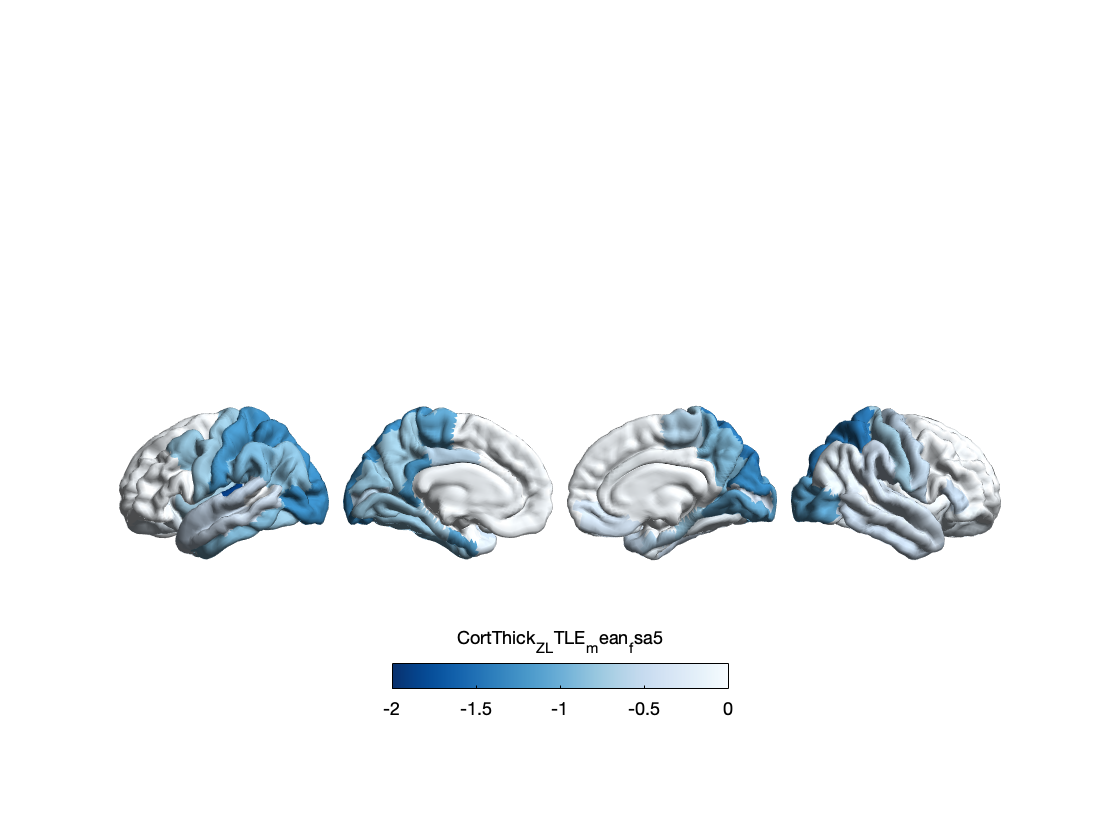

colormap(flipud(Blues)); colorbar_range([-2, 0]) 

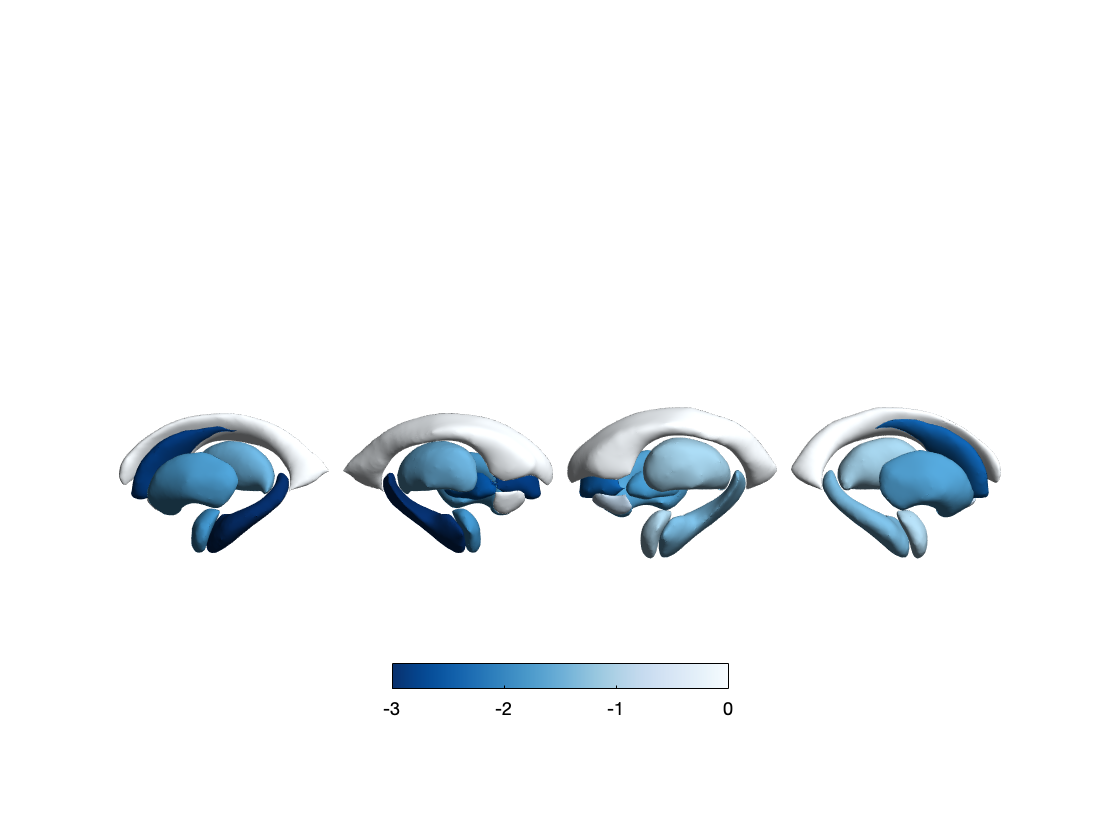

    
plot_subcortical(SubVol_Z_LTLE_r_mean{:, :})
colormap(flipud(Blues)); colorbar_range([-3, 0]) 

## Figure 3b. Fetch disease-related gene expression data

% Fetch gene expression data
[genes, ~, genelabels] = fetch_ahba();

% Get the names of epilepsy-related genes (Focal HS phenotype)
epilepsy_genes = risk_genes('epilepsy');
epilepsy_genes = find(ismember(genelabels, epilepsy_genes.focalhs));

% Extract gene expression data for epilepsy (Focal HS)
epilepsy_gene_data = genes(:, epilepsy_genes);


## Figure 4b. Load connectivity data

% Load functional connectivity data
[fc_ctx, fc_ctx_labels, fc_sctx, fc_sctx_labels] = load_fc();

% Load structural connectivity data
[sc_ctx, sc_ctx_labels, sc_sctx, sc_sctx_labels] = load_sc();

## Figure 5b. Hub susceptibility model

% Remove subcortical values corresponding to the ventricles
SubVol_Z_LTLE_r_mean_noVent               = SubVol_Z_LTLE_r_mean;
SubVol_Z_LTLE_r_mean_noVent.mean_LLatVent = [];
SubVol_Z_LTLE_r_mean_noVent.mean_RLatVent = [];

% Compute weighted degree centrality measures
fc_ctx_dc  = sum(fc_ctx, 1);
fc_sctx_dc = sum(fc_sctx, 2);

sc_ctx_dc  = sum(sc_ctx, 1);
sc_sctx_dc = sum(sc_sctx, 2);

% Perform spatial correlations between hubs and mean atrophy
fc_ctx_r  = corrcoef(fc_ctx_dc, CortThick_Z_LTLE_mean{:, :});
fc_sctx_r = corrcoef(fc_sctx_dc, SubVol_Z_LTLE_r_mean_noVent{:, :});

sc_ctx_r  = corrcoef(sc_ctx_dc, CortThick_Z_LTLE_mean{:, :});
sc_sctx_r = corrcoef(sc_sctx_dc, SubVol_Z_LTLE_r_mean_noVent{:, :});

## Figure 5e. Spin permutation testing

% Spin permutation testing for two cortical maps
fc_ctx_p  = spin_test(fc_ctx_dc, CortThick_Z_LTLE_mean{:, :}, ...
                     'fsa5', 1000, 'pearson');
sc_ctx_p  = spin_test(sc_ctx_dc, CortThick_Z_LTLE_mean{:, :}, ...
                     'fsa5', 1000, 'pearson');

% Shuf permutation testing for two subcortical maps 
fc_sctx_p = spin_test(fc_sctx_dc, SubVol_Z_LTLE_r_mean_noVent{:, :}, ...
                     1000, 'pearson');
sc_sctx_p = spin_test(sc_sctx_dc, SubVol_Z_LTLE_r_mean_noVent{:, :}, ...
                     1000, 'pearson');

## Figure 6b. Disease epicenter mapping

%% Figure 6b. Disease epicenter mapping
% Identify functional epicenters
fc_ctx_epi              = zeros(size(fc_ctx, 1), 1);
fc_ctx_epi_p            = zeros(size(fc_ctx, 1), 1);
for seed = 1:size(fc_ctx, 1)
    seed_conn           = fc_ctx(:, seed);
    r_tmp               = corrcoef(seed_conn, CortThick_Z_LTLE_mean{:, :});
    fc_ctx_epi(seed)    = r_tmp(1, 2);
    fc_ctx_epi_p(seed)  = spin_test(seed_conn, CortThick_Z_LTLE_mean{:, :}, ...
                                    'fsa5', 1000, 'pearson');
end

fc_sctx_epi             = zeros(size(fc_sctx, 1), 1);
fc_sctx_epi_p           = zeros(size(fc_sctx, 1), 1);
for seed = 1:size(fc_sctx, 1)
    seed_conn           = fc_sctx(seed, :);
    r_tmp               = corrcoef(seed_conn, CortThick_Z_LTLE_mean{:, :});
    fc_sctx_epi(seed)   = r_tmp(1, 2);
    fc_sctx_epi_p(seed) = spin_test(seed_conn, CortThick_Z_LTLE_mean{:, :}, ...
                                    'fsa5', 1000, 'pearson');
end

% Identify structural epicenters
sc_ctx_epi              = zeros(size(sc_ctx, 1), 1);
sc_ctx_epi_p            = zeros(size(sc_ctx, 1), 1);
for seed = 1:size(sc_ctx, 1)
    seed_conn           = sc_ctx(:, seed);
    r_tmp               = corrcoef(seed_conn, CortThick_Z_LTLE_mean{:, :});
    sc_ctx_epi(seed)    = r_tmp(1, 2);
    sc_ctx_epi_p(seed)  = spin_test(seed_conn, CortThick_Z_LTLE_mean{:, :}, ...
                                    'fsa5', 1000, 'pearson');
end

sc_sctx_epi             = zeros(size(sc_sctx, 1), 1); 
sc_sctx_epi_p           = zeros(size(sc_sctx, 1), 1); 
for seed = 1:size(sc_sctx, 1)
    seed_conn           = sc_sctx(seed, :);
    r_tmp               = corrcoef(seed_conn, CortThick_Z_LTLE_mean{:, :});
    sc_sctx_epi(seed)   = r_tmp(1, 2);
    sc_sctx_epi_p(seed) = spin_test(seed_conn, CortThick_Z_LTLE_mean{:, :}, ...
                                    'fsa5', 1000, 'pearson');
end